Once again, I'm going to simulate the diffusion of a random walker. This time, however, I'm going to compare the diffusion rates of calcium ions and a typical 300 amino acid protein inside a cell.

The formula for estimating diffusion time for a random walk simulation is t=<x^2>/2D, where D is the diffusion constant (D=(a^2)/2(delta)t, where a is the radius of the diffusing particle and delta t is the time unit)

r_Ca2+ = about 1 Angström (BNID 104164)

D_Ca2+ = (a^2)/2 = 0.5 (Angström^2)/s = 5(10)^-9 (um^2)/s

(plot time vs length)

Nsteps = 100; %Number of steps
Protein_Pos=zeros(Nsteps); %Distance traveled by a typical protein in E. coli cytoplasm (in micrometers)
P_time=zeros(Nsteps);
Ion_Pos=zeros(Nsteps); %Distance traveled by a Calcium ion (in micrometers)
I_time=zeros(Nsteps);

for i=2:Nsteps
    Protein_Pos(i)=Protein_Pos(i-1)+1;
    Ion_Pos(i)=Ion_Pos(i-1)+1;
    P_time(i)=(Protein_Pos(i)^2)/(2*3); %(D = 10(um^2)/s, class)
    I_time(i)=(Ion_Pos(i)^2)/(2*0.000000005); %(D = 0.000000005(um^2)/s, calculated)
end

Now plot time vs distance traveled.

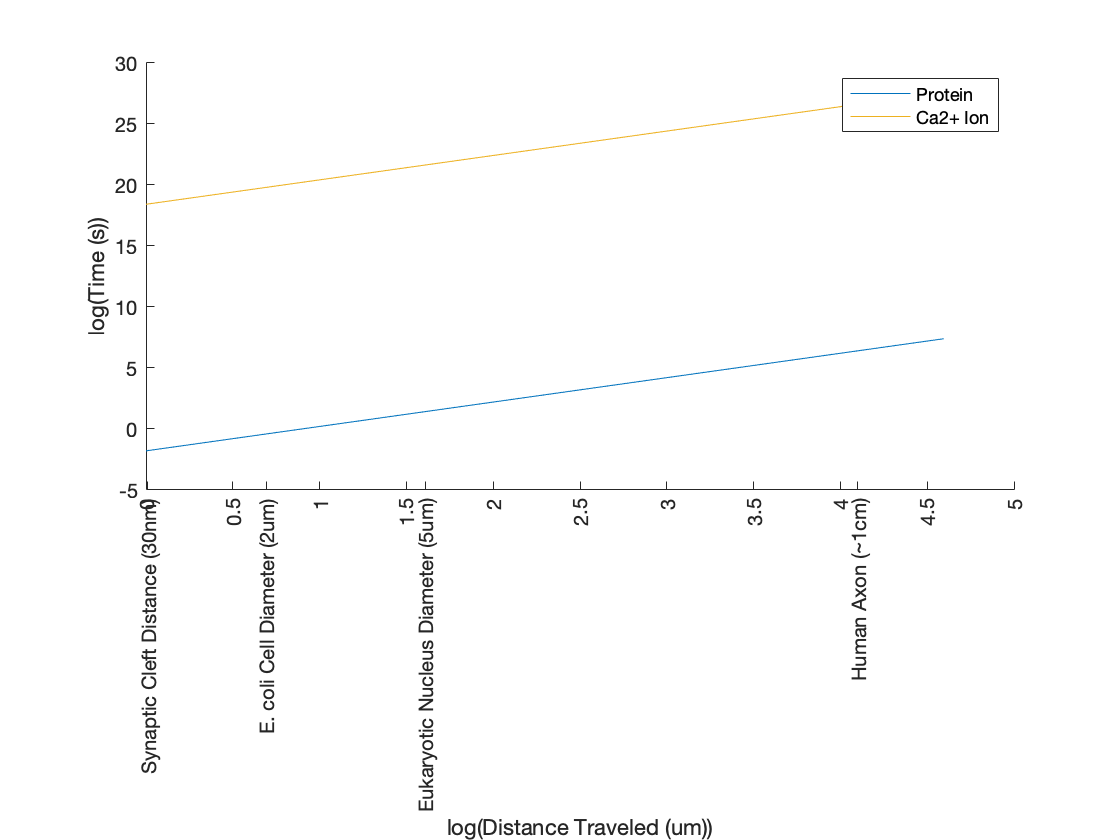

axon = log(10^4); %googling suggests that most axons aren't longer than a cm, but I can't find a solid source
Ecoli = log(2); %E. coli length = 2um (class)
synapse = log(0.03); %BNID 100721
eukaryote_nuc = log(5); %BNID 109953

hold on
protein = plot(log(Protein_Pos), log(P_time)); M1 = 'Protein';
ion = plot(log(Ion_Pos), log(I_time)); M2 = 'Ca2+ Ion';
xlabel('log(Distance Traveled (um))')
ylabel('log(Time (s))')

legend([protein(1);ion(1)],M1,M2);
set(gca,'XTick',[0,0.01,0.5,Ecoli,1,1.5,eukaryote_nuc,2,2.5,3,3.5,4,4.1,4.5,5])
set(gca,'XTickLabel',{'0','Synaptic Cleft Distance (30nm)','0.5','E. coli Cell Diameter (2um)','1','1.5','Eukaryotic Nucleus Diameter (5um)','2','2.5','3','3.5','4','Human Axon (average ~1cm)','4.5','5'})
set(gca, 'XTickLabelRotation', 90)

hold off